## Implementation Methods

Different Precision used by vpa

### Initialization

% cd 'F:\University\Semester IIX 2021\Detection & Estimation Theory\CA'
clear all; close all;
warning off
delta = eps^(2/3);
digits(2)  
% Actual d
d_a = 1e-5;
for k=1:31
  digits(k + 1);
  precision_digit(k) = digits;
  d(k) = vpa(d_a);

### Parameter of ill-conditioned Problem

  P  = eye(3);
  D0 = eye(3);
  U0 = eye(3);
  R  = d(k)^2*eye(2);
  H  = [1,1,1;1,1,1+d(k)];
  x0 = [1;1;-1];
  z  = H*x0 + d(k)*[randn;randn];

### Closed Form Solution

As a solution to compare different methods.  

  KCF = (1/(2*d_a*(d_a^2+d_a+4)))*[2*d_a+1,d_a-1;2*d_a+1,d_a-1;d_a-2,d_a^2+d_a+2];
  xCF = x0 + KCF*(z - H*x0);
  PCF = (1/(8+2*d_a*(1+d_a)))*[5+2*d_a*(1+d_a),-3,-2-d_a;-3,5+2*d_a*(1+d_a),-2-d_a;-2-d_a,-2-d_a,4+d_a^2];

### Standard KF

  K  = P*H'/(H*P*H'+R);
  xK = x0 + K*(z - H*x0);
  PK = P - K*H*P;

### Information Filter

  xI = x0 + (H'/R)*z;
  YI = inv(P) + (H'/R)*H;
  PI = inv(YI);

### Carlson Square Filter

  z1 = z(1);
  z2 = z(2);
  H1 = H(1,:);
  H2 = H(2,:);
  R1 = R(1,1);
  R2 = R(2,2);
  C0 = utcholesky(P);
  [x1,C1] = carlson(z1,R1,H1,x0,C0);
  [x2,C2] = carlson(z2,R2,H2,x1,C1);
  PC = C2*C2';

### Comparison

  rssCF = 0; % for closed form solution
  rssK  = 0; % for Kalman solution
  rssI  = 0; % for Information solution
  rssC  = 0; % for Carlson solution
    for i=1:3
      for j=1:3
      rssCF = rssC + PCF(i,j)^2;
      if (isnan(PI(i,j)))
        PI(i,j)=0;
      end
      if (isinf(PI(i,j)))
        PI(i,j)=1e5;
      end
      if (isnan(PK(i,j)))
        PK(i,j)=0;
      end
      if (isinf(PK(i,j)))
        PK(i,j)=1e5;
      end
      if (isnan(PC(i,j)))
        PC(i,j)=0;
      end
      if (isinf(PC(i,j)))
        PC(i,j)=1e5;
      end
      rssI = rssI + (PI(i,j)  - PCF(i,j))^2;
      rssK = rssK + (PK(i,j)  - PCF(i,j))^2;
      rssC = rssC + (PC(i,j)  - PCF(i,j))^2;
      end
    end
%
% Compute relative differences and limit rel. error to 10^4
%
  rdCF(k) = sqrt(rssCF/rssCF);
  rdK(k) = sqrt(rssK/rssCF);
  rdC(k) = sqrt(rssC/rssCF);
  rdI(k) = sqrt(rssI/rssCF);
end

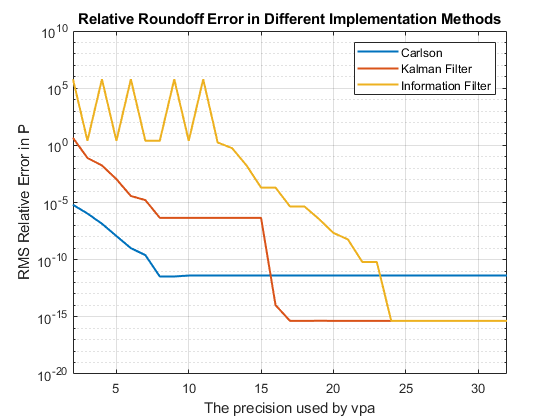

semilogy(precision_digit,rdC,precision_digit,rdK,precision_digit,rdI,'LineWidth',1.5)
xlim([2 32])
grid on
title('Relative Roundoff Error in Different Implementation Methods')
ylabel('RMS Relative Error in P')
xlabel('The precision used by vpa')
legend 'Carlson' 'Kalman Filter' 'Information Filter'

d

$$d = \left(\begin{array}{ccccccccccccccccccccccccccccccc} 0.0000099999999996214228303870186209679 & 0.000010000000000065512040237081237137 & 0.000010000000000010000889005823410116 & 0.0000099999999999995925481499625675497 & 0.000010000000000000026229018956769323 & 0.0000099999999999999991239646446317124 & 0.000010000000000000000818030539140313 & 0.0000099999999999999999709975918860128 & 0.0000099999999999999999974673714877096 & 0.000010000000000000000000776093937922 & 0.0000099999999999999999999489133253687 & 0.000010000000000000000000000612113653 & 0.000010000000000000000000000612113653 & 0.000010000000000000000000000006268478 & 0.000010000000000000000000000006268478 & 0.0000099999999999999999999999999575908 & 0.0000099999999999999999999999999575908 & 0.000010000000000000000000000000006895 & 0.000010000000000000000000000000000732 & 0.0000099999999999999999999999999999613 & 0.000010000000000000000000000000000009 & 0.00001 & 0.00001 & 0.00001 & 0.00001 & 0.00001 & 0.00001 & 0.00001 & 0.00001 & 0.00001 & 0.00001 \end{array}\right)$$